%% Specify Crystal and Specimen Symmetries

CS = {'notIndexed',...
  crystalSymmetry('622', [3.2 3.2 5.2], 'X||a', 'Y||b*', 'Z||c', 'mineral', 'Mg', 'color', 'light blue')};

% plotting conventions
setMTEXpref('xAxisDirection','east');
setMTEXpref('zAxisDirection','intoPlane');



%% Specify File Names

% path to files
pname = 'E:\Dropbox\Research\Tutorials\MTEX Twin Area extraction\WE43\0.08strain';

% which files to be imported
% fname = [pname '\0.08strain.ang'];0.08strain_minimalCleanup.ang
fname = [pname '\0.08strain.ang'];

%% Import the Data

% create an EBSD variable containing the data
ebsd = loadEBSD(fname,CS,'interface','ang')%,...%'convertSpatial2EulerReferenceFrame');...

 
ebsd = EBSD (show methods, plot)
 
 Phase   Orientations  Mineral       Color  Symmetry  Crystal reference frame
     0  292354 (100%)       Mg  light blue       622       X||a, Y||b*, Z||c*
 
 Properties: ci, fit, iq, sem_signal, unknown1, unknown2, unknown3, unknown4, x, y
 Scan unit : um
 


  I'm going to colorize the orientation data with the 
  standard MTEX colorkey. To view the colorkey do:
 
  oM = ipdfHSVOrientationMapping(ori_variable_name)
  plot(oM)


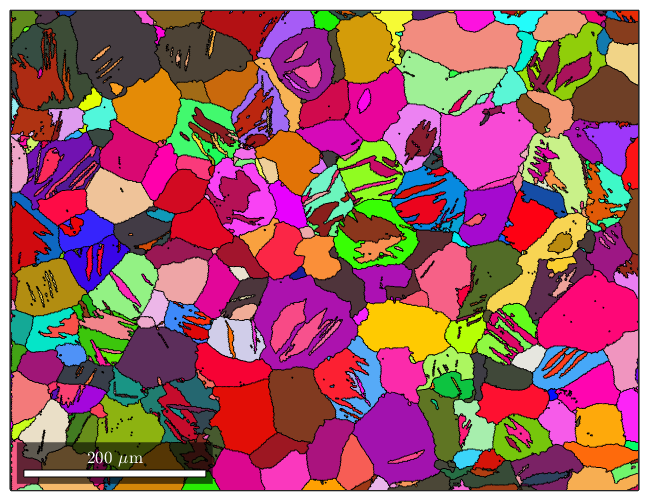

ebsd(ebsd.prop.iq==0).phaseId=1;
ebsd=ebsd(ebsd.prop.ci>0.1);

% figure; plot(ebsd)
% ebsd=ebsd('indexed')
%    'convertEuler2SpatialReferenceFrame');
% odf1 = calcODF(ebsd.orientations)
h = [Miller(1,0,-1,0,CS{2}),Miller(0,0,0,2,CS{2})];
% figure
% plotPDF(odf1,h,'antipodal')
% % define a sub region
% xmin = min(ebsd.prop.x);
% xmax = max(ebsd.prop.x);%/3;
% ymin = min(ebsd.prop.y);
% ymax = max(ebsd.prop.y);
% 
% region = [xmin ymin xmax-xmin ymax-ymin];
% 
% % visualize the whole data set
% plot(ebsd)
% % and marke the sub region
% rectangle('position',region,'edgecolor','r','linewidth',2)
% 
% % select EBSD data within region
% condition = inpolygon(ebsd,region); % select indices by polygon
% ebsd = ebsd(condition);

% ebsd=ebsd('notIndexed');
oM = ipdfHSVOrientationMapping(ebsd('indexed'));
color = oM.orientation2color(ebsd('indexed').orientations);
% figure;plot(oM); %IPF triangle
% figure;plot(ebsd,color); %EBSD IPF map
% Reconstruct grains
% segmentation angle typically 10 to 15 degrees that seperates to grains
seg_angle = 5;

% minimum indexed points per grain between 5 and 10
min_points = 5;

[grains,ebsd.grainId,ebsd.mis2mean] = calcGrains(ebsd('indexed'),...
    'angle',seg_angle*degree);
% notIndexed = grains('notIndexed')
% the "not indexed grains" we want to remove
% toRemove = notIndexed(notIndexed.grainSize ./ notIndexed.boundarySize<0.75)

% now we remove the corresponding EBSD measurements
% ebsd(toRemove) = []

% and perform grain reconstruction with the reduces EBSD data set
% [grains,ebsd.grainId,ebsd.mis2mean] = calcGrains(ebsd);

% remove small grains with less than min_points indexed points
figure;plot(grains('Mg'),grains('Mg').meanOrientation)


grainsSelected = grains(grains.grainSize > 5);

%reindex ebsd 
ebsd = ebsd(grainsSelected);
% figure;plot(grains('Mg'),grains('Mg').meanOrientation)

% and perform grain reconstruction with the reduces EBSD data set
[grains,ebsd.grainId,ebsd.mis2mean] = calcGrains(ebsd('indexed'),'angle',5*degree);

% figure;plot(grains('Mg'),grains('Mg').meanOrientation)

% figure; plot(ebsd('indexed'),ebsd('indexed').orientations)

## We need to use the mean misorientation between twin/parent to group grains using a graph theory base.

%for each grain we want to look at neighbors and build the connectivity that appropriately clusters grains 


numGrains = 590

tol=8*degree;

[counts,pairs] = neighbors(grains)

counts =      3
     2
     1
     3
     3
     3
     3
     2
     2
     2


pairs =      1    14
     1    28
     1    59
     2    23
     2    40
     3    10
     4    13
     4    49
     4    67
     5     8


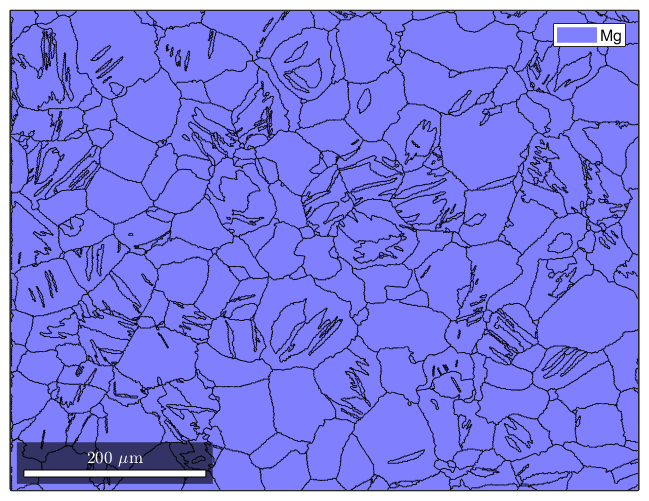

combine=zeros(length(pairs),1,'logical');
for i=1:length(pairs)
    mori=inv(grains(pairs(i,1)).meanOrientation)*grains(pairs(i,2)).meanOrientation; %Compute misorientation between all pairs
    combine(i) = TestTwinRelationship(ebsd,mori,tol);
end

figure;plot(grains(pairs(combine,1:2)))

## Now we need to make a list of boundaries shared between the grains

 
grain1 = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0     459  115245       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 39130
 triple points: 752
 
 Properties: GOS, meanRotation
 


 
grain2 = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0     459  539064       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 46929
 triple points: 861
 
 Properties: GOS, meanRotation
 


 
ans = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0     918  654309       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 49183
 triple points: 882
 
 Properties: GOS, meanRotation
 


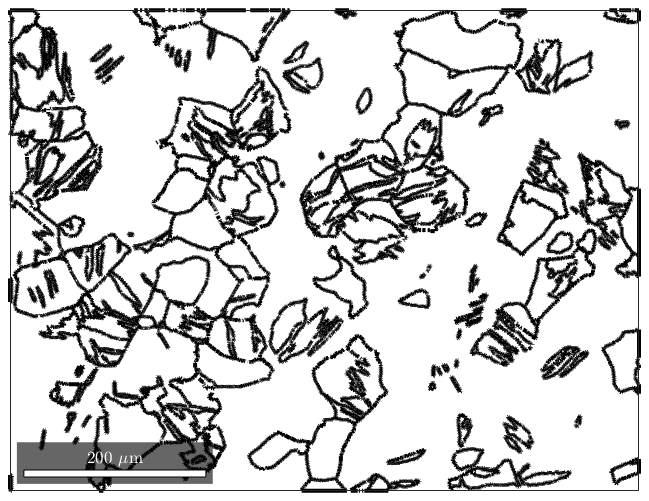

% boundary2Merge=grains(pairs(combine,1)).boundary.==grains(pairs(combine,2)).boundary
boundarList=[];
grain1=grains(pairs(combine,1))
grain2=grains(pairs(combine,2))
for i=1:length(grain1)

    x1=grain1(i).boundary.x;
    y1=grain1(i).boundary.y;
    x2=grain2(i).boundary.x;
    y2=grain2(i).boundary.y;
    [boundarLoc,loc]=intersect([x1,y1],[x2,y2],'rows');
    % scatter(boundarLoc(:,1),boundarLoc(:,2))
%     plot(grain1.boundary(loc),'k','linewidth',3)
%     hold off

%Since this clearly works 
[mergedGrains,parentId] = merge(grains,grain1.boundary(loc));
% copy ebsd data into a new variable to not change the old data
ebsd_merged = ebsd;
% update the grainIds to the parentIds
ebsd_merged('indexed').grainId = parentId(ebsd('indexed').grainId)
figure
plot(ebsd_merged('Mg'),ebsd('Mg').orientations)
hold on 
plot(mergedGrains.boundary,'k','linewidth',3)
hold off

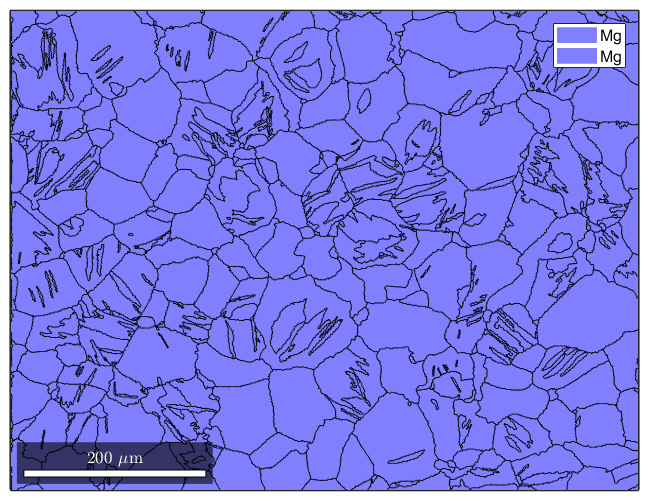


plot(grains)
hold on
plot(grains(pairs(163,1:2)),'yellow')
hold off

 
grains2merge = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0     918  654309       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 49183
 triple points: 882
 
 Properties: GOS, meanRotation
 


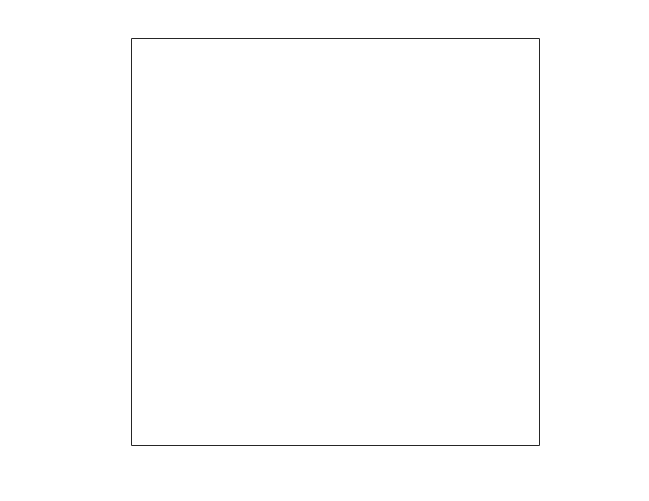

 
grain1 = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0       1      10       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 20
 triple points: 2
 
 Id   Phase   Pixels         GOS   phi1   Phi   phi2
  1       0       10   0.0144637    108    47    330
 


 
grain2 = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0       1       7       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 17
 triple points: 1
 
 Id   Phase   Pixels          GOS   phi1   Phi   phi2
  2       0        7   0.00939301     82    48     83
 


 
grain3 = grain2d (show methods, plot)
 
 Phase  Grains  Pixels  Mineral  Symmetry  Crystal reference frame
     0       2      17       Mg       622       X||a, Y||b*, Z||c*
 
 boundary segments: 37
 triple points: 2
 
 Id   Phase   Pixels          GOS   phi1   Phi   phi2
  1       0       10    0.0144637    108    47    330
  2       0        7   0.00939301     82    48     83
 


 
test = grainBoundary (show methods, plot)
 
 Segments  mineral 1  mineral 2
       27         Mg         Mg


Index exceeds matrix dimensions.

Error in grain2d/subSet (line 31)
grains.inclusionId = grains.inclusionId(ind);

Error in grain2d/plot (line 89)
    color = grains.subSet(ind).color;


[mergedGrains,parentId] = merge(grains,combinedTwin);
% copy ebsd data into a new variable to not change the old data
ebsd_merged = ebsd;
% update the grainIds to the parentIds
ebsd_merged('indexed').grainId = parentId(ebsd('indexed').grainId)
figure
plot(ebsd_merged('Mg'),ebsd('Mg').orientations)
hold on 
plot(mergedGrains.boundary,'k','linewidth',3)
hold off




% hold on
% plot(grains2merge('Mg','Mg'),'linewidth',3)
% hold off


% for i=1:numGrains
%     if ~ismember(i,processNeighbors)
%         cnt=cnt+1;
%         processNeighbors(cnt)=i;
%     end
%     
%     while length(processNeighbors)<=cnt
%         [counts,pairs] = neighbors(grains(grainId))
%         group=zeros(counts,1,'logical');
%         for j=1:counts
%             mis=angle(grains(i).meanOrientation,grains(pairs(j,2)).meanOrientation) / degree
%             twinDected = TestTwinRelationship(ebsd,mis,tol)
%             if twinDetected
%                 
%             end
%         end
% end

gB = grains.boundary

 
gB = grainBoundary (show methods, plot)
 
 Segments   mineral 1  mineral 2
     1632  notIndexed         Mg
    50400          Mg         Mg


gB_MgMg = gB('Mg','Mg')

 
gB_MgMg = grainBoundary (show methods, plot)
 
 Segments  mineral 1  mineral 2
    50400         Mg         Mg




% figure
plot(grains('Mg'),grains('Mg').meanOrientation)

  I'm going to colorize the orientation data with the 
  standard MTEX colorkey. To view the colorkey do:
 
  oM = ipdfHSVOrientationMapping(ori_variable_name)
  plot(oM)


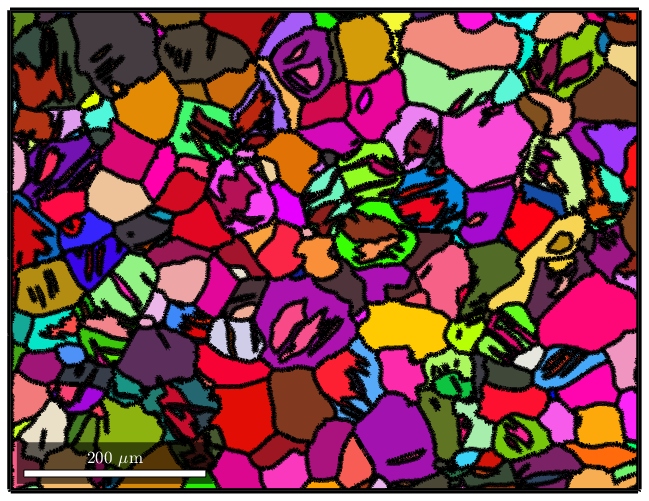

% plot(ebsd('Mg'),ebsd('Mg').orientations)
hold on
% plot the boundary of all grains
plot(grains.boundary,'linewidth',4)
hold off

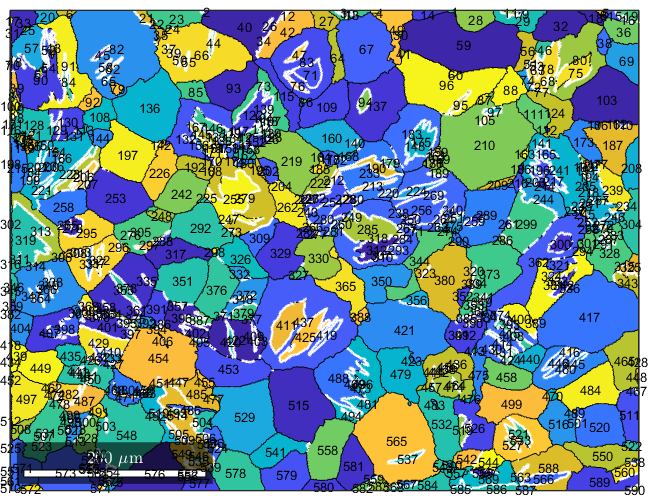

%% Get twin boundaries
[twinBoundary_tt1,twinBoundary_tt2,twinBoundary_ct1,twinBoundary_sec1,twinBoundary_ttwint] = GetTwinBoundaries(ebsd,gB_MgMg,5*degree);

% plot the twinning boundaries
% figure
plot(grains('Mg'),grains('Mg').id(randperm(length(grains('Mg')))))
% plot(ebsd,ebsd.orientations)
hold on
%plot(gB_MgMg,angle(gB_MgMg.misorientation,twinning),'linewidth',4)
plot(twinBoundary_tt1,'linecolor','w','linewidth',2,'displayName','Tensile Twin 1 Boundary')
plot(twinBoundary_tt2,'linecolor','w','linewidth',2,'displayName','Tensile Twin 2 Boundary')
plot(twinBoundary_ct1,'linecolor','w','linewidth',2,'displayName','Compression Twin 1 Boundary')
plot(twinBoundary_sec1,'linecolor','w','linewidth',2,'displayName','Secondary Twin 1 Boundary')
plot(twinBoundary_ttwint,'linecolor','w','linewidth',2,'displayName','Tensile-Tensile Twin Boundary')
text(grains,int2str(grains.id))
hold off

legend off

%% Merge grains and label the parent grains
combinedTwinTot=[twinBoundary_tt1;twinBoundary_tt2;twinBoundary_sec1;twinBoundary_ttwint] %;twinBoundary_ct1 excluded because easy to identify

 
combinedTwinTot = grainBoundary (show methods, plot)
 
 Segments  mineral 1  mineral 2
    22065         Mg         Mg


combinedTwin=combinedTwinTot;

%% Compute the misorientation between mean orientations to segment the microstructure 



%% Need to remove twin boundary for merging that lies on parent grain boundaries.
numGrains=grains.length

numGrains = 590

ratio_gBs=zeros(numGrains,1)

ratio_gBs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=1:numGrains
    
    %Check if is x,y against all boundaries
    %If a twin has a twin boundary relationship with
    
    
    grainIdGlobal=or(gB_MgMg.grainId(:,1)==i,gB_MgMg.grainId(:,2)==i);
    grainIdTwin=or(combinedTwin.grainId(:,1)==i,combinedTwin.grainId(:,2)==i);
    tmp_gB=gB_MgMg(grainIdGlobal);
    tmp_gB_isTwinning=combinedTwin(grainIdTwin);
    
    ratio_gBs(i)=length(tmp_gB_isTwinning)/length(tmp_gB);
    if ratio_gBs(i)<0.0 && ratio_gBs(i) > 0
        combinedTwin(grainIdTwin)=[];
    end
end


% figure
% plot(grains)
% hold on
% % plot the boundary of all grains
% plot(,'linewidth',4)
% % plot(combinedTwin(grainIdTwin),'linewidth',4,'linecolor','w')
% hold off



[mergedGrains,parentId] = merge(grains,combinedTwin);
% copy ebsd data into a new variable to not change the old data
ebsd_merged = ebsd;
% update the grainIds to the parentIds
ebsd_merged('indexed').grainId = parentId(ebsd('indexed').grainId)

 
ebsd_merged = EBSD (show methods, plot)
 
 Phase   Orientations  Mineral       Color  Symmetry  Crystal reference frame
     0  268617 (100%)       Mg  light blue       622       X||a, Y||b*, Z||c*
 
 Properties: ci, fit, iq, sem_signal, unknown1, unknown2, unknown3, unknown4, x, y, grainId, mis2mean
 Scan unit : um
 


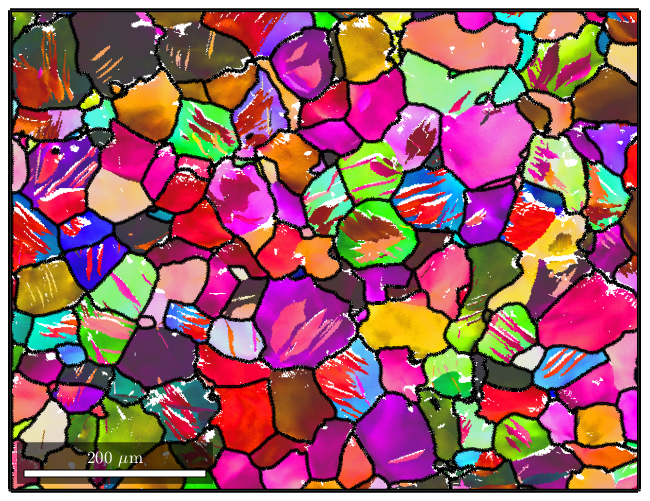

figure

plot(ebsd_merged('Mg'),ebsd('Mg').orientations)

  I'm going to colorize the orientation data with the 
  standard MTEX colorkey. To view the colorkey do:
 
  oM = ipdfHSVOrientationMapping(ori_variable_name)
  plot(oM)


hold on 
plot(mergedGrains.boundary,'k','linewidth',3)
hold off

[twinBoundary_tt1,twinBoundary_tt2,twinBoundary_ct1,twinBoundary_sec1,twinBoundary_ttwint] = GetTwinBoundaries(ebsd,gB_MgMg,5*degree);
[mergedGrains,parentId] = merge(mergedGrains,combinedTwinTot);

Error using sparse
Index exceeds matrix dimensions.

Error in grain2d/merge (line 45)
A = sparse(mergeId(:,1),mergeId(:,2),1,length(grains),length(grains));

% plot the merged grains
%plot(ebsd,ebsd.orientations)
figure
plot(mergedGrains.boundary,'linecolor','k','linewidth',2.5,'linestyle','-',...
  'displayName','merged grains')
hold on
text(mergedGrains,int2str(mergedGrains.id))
plot(twinBoundary_tt1,'linecolor','r','linewidth',2,'displayName','Tensile Twin 1')
plot(twinBoundary_tt2,'linecolor','g','linewidth',2,'displayName','Tensile Twin 2')
plot(twinBoundary_ct1,'linecolor','b','linewidth',2,'displayName','Compression Twin')
plot(twinBoundary_sec1,'linecolor','y','linewidth',2,'displayName','Secondary Twin')
plot(twinBoundary_ttwint,'linecolor','c','linewidth',2,'displayName','Tensile-Tensile Twin Boundary')
hold off
legend off

%% Loop over grains and pull twins out by their size in pixels
% gBInner=mergedGrains.innerBoundary;
% gBPar
% isTwinning = angle(gBInner.misorientation,tt1) < 7.5*degree;
% twinBoundaryInner=gBInner(isTwinning)

%Note: the parent ID maps each grain in original scan to a merged grain. 
%We want to to extract all of the grains within a merged grain. Finally we
%Want to reform the parent grain and visualize the result to make sure the
%algorithm is doing what we want. 

% Make grain id map and compare to IPF map
% figure
% plot(grains,grains.id(randperm(length(grains))),'micronbar','off','figSize','large')
% hold on
% plot(grains.boundary)
% mtexColorMap hsv
% hold off

% color = oM.orientation2color(ebsd.orientations);
% figure;
% plot(ebsd,color,'micronbar','off','figSize','large')

%from here we need to compute:
%1) should have check for 
%1)twin boundary length for all boundary types: parent, neighbor, twin-twin
%2)group merged grains by misorientation 
%3)grain area
%4)schmid factor at parent/twin boundary for twin type

%with this data in arrays we can:
%1) apply voting scheme to segment structure and assign twin types
%2) compute twin thickness 
%3) varient type



%reconstruction strategy is 
isTwin=zeros(length(grains),1);
nmerged=length(mergedGrains)

nmerged = 254

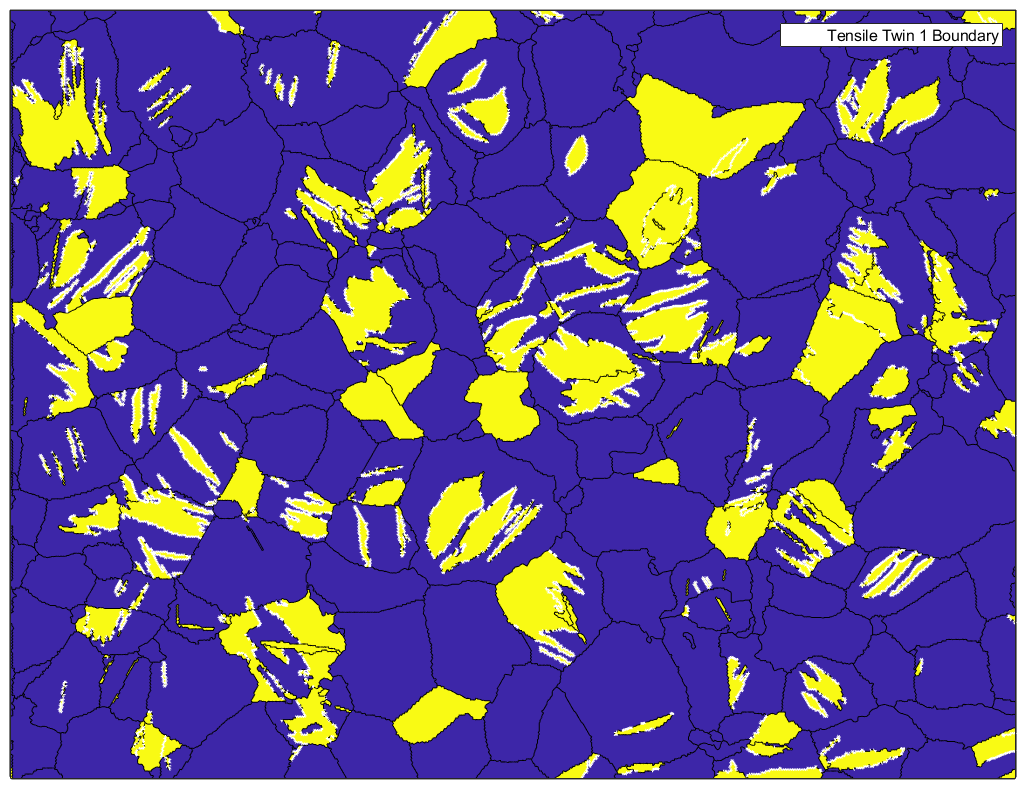

for i=1:nmerged
    subgrains = grains(parentId == mergedGrains(i).id);
    maxArea=max(subgrains.grainSize);
    % need to group similar same orientations into single parent grain so
    % we compute the misorientation between mean components   
    flag=false; cnt=1;
    while cnt <=length(subgrains) && flag==false
        mis=angle(subgrains(cnt).meanOrientation, subgrains.meanOrientation)./degree;
        area=sum(subgrains.grainSize(mis<5));
        if area >=maxArea
            isTwin(subgrains(mis>5).id)=1;
            flag=true;
        end
        cnt=cnt+1;
    end
end 
% figure
plot(grains,isTwin,'micronbar','off','figSize','large')
hold on
% plot(grains.boundary)
plot(twinBoundary_tt1,'linecolor','w','linewidth',2,'displayName','Tensile Twin 1 Boundary')
hold off